clear; clc;
fs = 44100;

tones = [1, 1, 5, 5, 6, 6, 5]; 
rhythms = [0.5, 0.5, 0.5, 0.5, 0.5, 0.5, 1.0]; 
scale = 'C'; 
music_exp = gen_music_envelope(tones, scale, rhythms, fs, 'exponential');
music_lin = gen_music_envelope(tones, scale, rhythms, fs, 'linear');
music_sin = gen_music_envelope(tones, scale, rhythms, fs, 'sine');

%平方衰减 (新增：急促的拨弦感)
% 公式：(1 - t/T)^2
music_sqr = gen_music_envelope(tones, scale, rhythms, fs, 'square');

%高斯衰减 (新增：柔和的钟声感)
% 公式：exp(-t^2)
music_gau = gen_music_envelope(tones, scale, rhythms, fs, 'gaussian');

fprintf('1. 指数衰减 (Exponential)...\n');

1. 指数衰减 (Exponential)...


sound(music_exp, fs);
audiowrite('star_exponential.wav', music_exp, fs);
pause(3.5);

fprintf('2. 线性衰减 (Linear)...\n');

2. 线性衰减 (Linear)...


sound(music_lin, fs);
audiowrite('star_linear.wav', music_lin, fs);
pause(3.5);

fprintf('3. 正弦隆起 (Sine)...\n');

3. 正弦隆起 (Sine)...


sound(music_sin, fs);
audiowrite('star_sine.wav', music_sin, fs);
pause(3.5);

fprintf('4. 平方衰减 (Square)...\n');

4. 平方衰减 (Square)...


sound(music_sqr, fs);
audiowrite('star_square.wav', music_sqr, fs);
pause(3.5);

fprintf('5. 高斯衰减 (Gaussian)...\n');

5. 高斯衰减 (Gaussian)...


sound(music_gau, fs);
audiowrite('star_gaussian.wav', music_gau, fs);
pause(3.5);

fprintf('播放结束，正在绘制对比图...\n');

播放结束，正在绘制对比图...


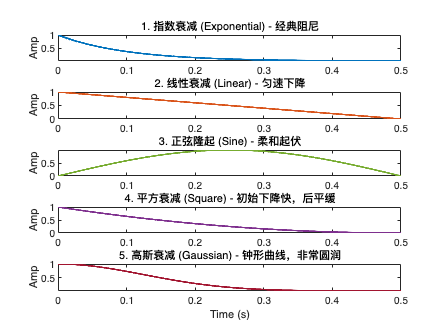

duration = 0.5;
t = linspace(0, duration, round(duration*fs));
x = linspace(0, 1, length(t));
env_exp = exp(-5 * x);          % 指数
env_lin = 1 - x;                % 线性
env_sin = sin(pi * x);          % 正弦隆起
env_sqr = (1 - x).^2;           % 平方
env_gau = exp(-8 * x.^2);       % 高斯

figure('Color', 'w', 'Name', 'Envelope Comparison');

subplot(5,1,1);
plot(t, env_exp, 'LineWidth', 2, 'Color', '#0072BD');
title('1. 指数衰减 (Exponential) - 经典阻尼'); axis tight; ylabel('Amp');

subplot(5,1,2);
plot(t, env_lin, 'LineWidth', 2, 'Color', '#D95319');
title('2. 线性衰减 (Linear) - 匀速下降'); axis tight; ylabel('Amp');

subplot(5,1,3);
plot(t, env_sin, 'LineWidth', 2, 'Color', '#77AC30');
title('3. 正弦隆起 (Sine) - 柔和起伏'); axis tight; ylabel('Amp');

subplot(5,1,4);
plot(t, env_sqr, 'LineWidth', 2, 'Color', '#7E2F8E');
title('4. 平方衰减 (Square) - 初始下降快，后平缓'); axis tight; ylabel('Amp');

subplot(5,1,5);
plot(t, env_gau, 'LineWidth', 2, 'Color', '#A2142F');
title('5. 高斯衰减 (Gaussian) - 钟形曲线，非常圆润'); axis tight; ylabel('Amp'); xlabel('Time (s)');


function full_wave = gen_music_envelope(tones, scale, rhythms, fs, type)
    full_wave = [];
    noctave = 0; rising = 0;
    
    for i = 1:length(tones)
        duration = rhythms(i);
        t = linspace(0, duration, round(duration * fs));
        x = linspace(0, 1, length(t)); 
        f = tone2freq2(tones(i), scale, noctave, rising);
        raw_wave = sin(2 * pi * f * t);

        switch type
            case 'exponential'
                env = exp(-5 * x); 
            case 'linear'
                env = 1 - x;
            case 'sine'
                env = sin(pi * x);
            case 'square'
                env = (1 - x).^2;
            case 'gaussian'
                env = exp(-8 * x.^2);
        end
        
        full_wave = [full_wave, raw_wave .* env];
    end
end

function freq = tone2freq2(tone, scale, noctave, rising)
    base = 261.63; 
    dic = [0, 2, 4, 5, 7, 9, 11];
    n = dic(tone);
    freq = base * (2 ^ (n / 12));
end